## Inverse design of a 5-segment arm

Given a load for a 5-segment arm and a target overall curvature and length, find the individual segment dimensions that are capable of creating the requisite internal reaction forces and moments

N_segs = 5;
Q = [0; -3; 0];
p = [0; 80];

%seg_g_circ_right_goal = [0.1; 0; 0.1];  
%overall_g_circ_right_goal = diag([N_segs, 1, N_segs]) * seg_g_circ_right_goal;

overall_g_circ_right_goal = [0.5; 0; 0.5];
seg_g_circ_right_goal = overall_g_circ_right_goal / N_segs;

A naive solution, such as a constant radius arm, cannot reach our desired shape. Due to load, the curvature along the arm will vary. 

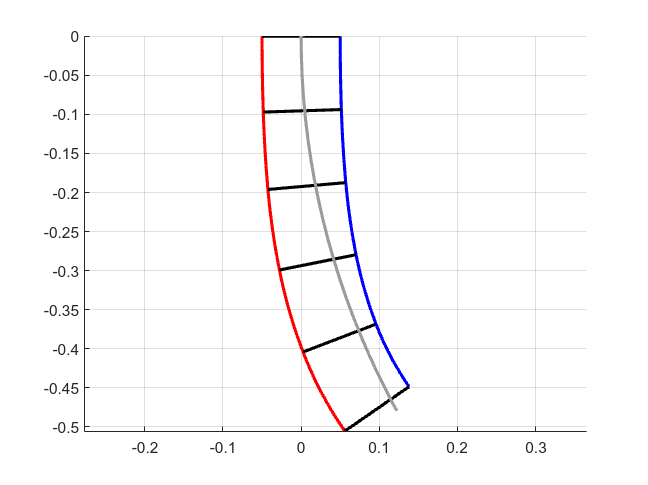

l_0 = overall_g_circ_right_goal(1) * 1.15;
rho_base = 0.03;
rho_tip = 0.08;

rho_constant = 0.05;

test_straight_arm = ArmSeriesFactory.constant_2d_muscle_arm(N_segs, rho_constant, l_0);
test_taper_arm = ArmSeriesFactory.tapered_2d_muscle_arm(N_segs, rho_base, rho_tip, l_0);
test_straight_arm.set_mechanics(GinaMuscleMechanics(l_0));
test_taper_arm.set_mechanics(GinaMuscleMechanics(l_0));

g_circ_right_actual = test_straight_arm.solve_equilibrium_gina(p, Q);
%test_taper_arm.solve_equilibrium_gina(p, Q);

ax = axes(figure());
Plotter2D.plot_arm_series(test_straight_arm, ax);
%Plotter2D.plot_arm_series(test_taper_arm, ax);

target_rod = RodSegment(Pose2, overall_g_circ_right_goal(1), test_straight_arm.segments(1).g_0_o);
target_rod.g_circ_right = overall_g_circ_right_goal;
Plotter2D.plot_rod(target_rod, ax); 

Let's take a step back and look at the reaction moments each segment needs to generate to be able to sustain this desired shape.

Find the requisite internal force and moment reactions needed to maintain that shape with the load

arm_g_circ_right_goal = repmat(overall_g_circ_right_goal, [1, N_segs]);
rxn_needed = test_straight_arm.calc_external_reaction(Q, arm_g_circ_right_goal);
internal_needed = -rxn_needed

internal_needed =    -3.0000   -2.9850   -2.9402   -2.8660   -2.7632
    0.0000    0.2995    0.5960    0.8866    1.1683
    0.3673    0.3523    0.3075    0.2333    0.1304


A naive solution, such as a straight arm or naively tapered arm, cannot sustain a constant curvature under our specified load

seg_l_0 = seg_g_circ_right_goal(1);

N_rhos = 20;
N_ls = 20;
rhos = linspace(0.015, 0.15, N_rhos);
l_0s = linspace(0.55, 0.6, N_ls);

cell_rl = cell(N_rhos, N_ls);
cell_arm_segments = cell(N_rhos, N_ls);
cell_rxns = cell(N_rhos, N_ls);
cell_colors = cell(N_rhos, N_ls);
for i = 1 : N_rhos
    rho_i = rhos(i);
    for j = 1 : N_ls
        l_0_j = l_0s(j);
        % Calculate the internal reaction moment that the muscles would create
        % at that curvature.
        segment_ij = ArmSegmentFactory.make_2d_2muscle(rho_i, l_0_j);
        segment_ij.set_mechanics(GinaMuscleMechanics(l_0_j));
    
        cell_arm_segments{i, j} = segment_ij;
        cell_rl{i, j} = [rho_i; l_0_j];
        cell_rxns{i, j} = segment_ij.calc_internal_reaction([0; 80], overall_g_circ_right_goal);
        cell_colors{i, j} = [i/N_rhos * 0.8; j/N_ls * 0.75 + 0.25; 1];
    end
end

mat_rl = [cell_rl{:}];
mat_rxns = [cell_rxns{:}];
mat_hsv = [cell_colors{:}];
mat_rgb = hsv2rgb(mat_hsv');

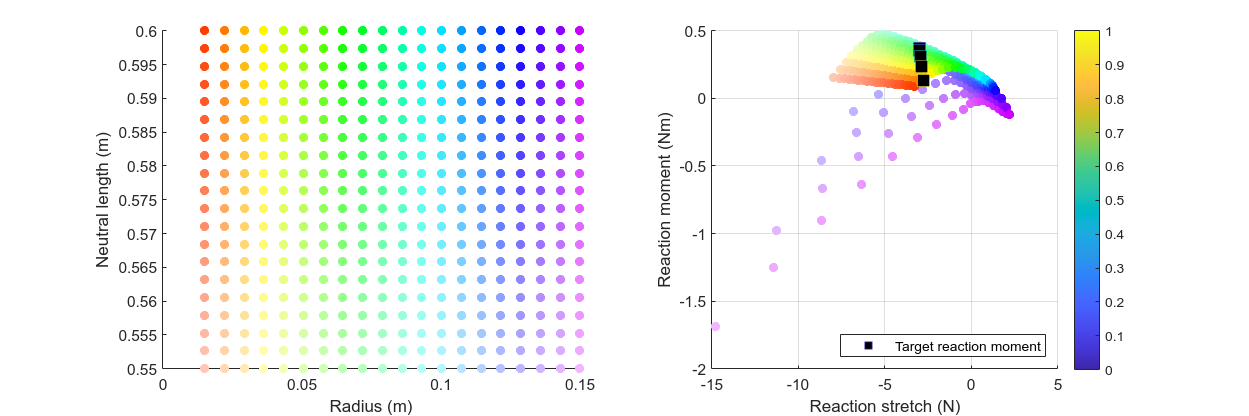

figure("Position", [0, 0, 1500, 500])
subplot(1, 2, 1);
scatter(mat_rl(1, :), mat_rl(2, :), [], mat_rgb, "filled");
xlabel("Radius (m)");
ylabel("Neutral length (m)")

subplot(1, 2, 2);
hold on
scatter(mat_rxns(1, :), mat_rxns(3, :), [], mat_rgb, "filled");
scatter(internal_needed(1, :), internal_needed(3, :), 100, linspace(0, 1, N_segs), 'square', "markerfacecolor", 'k')
colorbar

grid on
xlabel("Reaction stretch (N)")
ylabel("Reaction moment (Nm)")
legend(["", "Target reaction moment"], "location", "southeast")

segments = ArmSegment.empty(0, N_segs);
for i = 1 : N_segs
    % For each moment needed, find the arm segment that is capable of
    % producing that. 
    goal_i = internal_needed(:, i);
    [~, i_arm] = min(vecnorm(mat_rxns - goal_i, 1));
    cell_col_arm_segments = cell_arm_segments(:);
    segments(i) = copy(cell_col_arm_segments{i_arm});
end
arm_series = ArmSeries(segments, override_max_s=false);

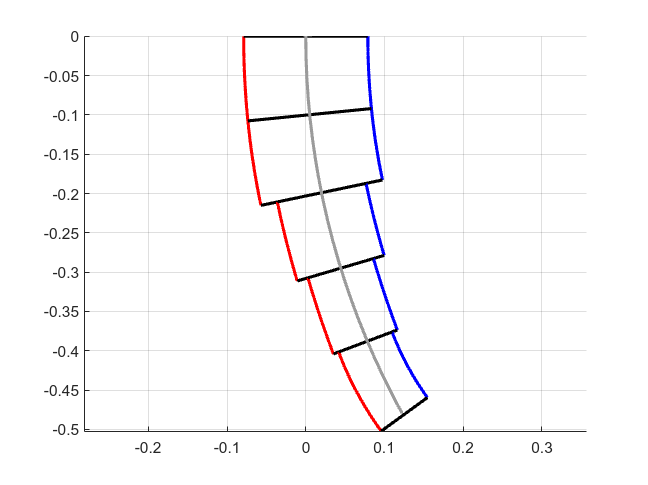

target_rod = RodSegment(Pose2, overall_g_circ_right_goal(1), segments(1).g_0_o);
target_rod.g_circ_right = overall_g_circ_right_goal;

arm_series.solve_equilibrium_gina(p, Q);
ax = axes(figure());
Plotter2D.plot_arm_series(arm_series, ax);
Plotter2D.plot_rod(target_rod, ax);

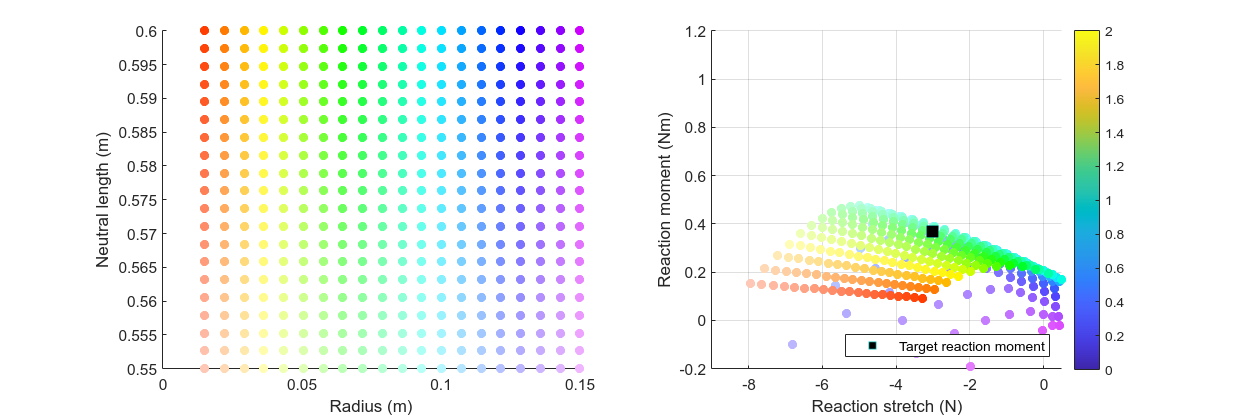

curvature = 0.5;
g_base = Pose2.hat([0; 0; -pi/2]);
g_circ_right = [0.5; 0; curvature];
rxn_needed = -inv(Pose2.adjoint(Twist2.expm(g_circ_right)))' * Pose2.left_lifted_action(g_base * Twist2.expm(g_circ_right))' * Q;
segments = inverse_design_segment(curvature, p, rxn_needed);
xlim([-9, 0.5]);
ylim([-0.2, 1.2]);

function segments = inverse_design_segment(curvature_goal, p, internal_needed)
    g_circ_right_goal = [0.5; 0; curvature_goal];
    N_segs = size(internal_needed, 2);

    N_rhos = 20;
    N_ls = 20;
    rhos = linspace(0.015, 0.15, N_rhos);
    l_0s = linspace(0.55, 0.6, N_ls);
    
    cell_rl = cell(N_rhos, N_ls);
    cell_arm_segments = cell(N_rhos, N_ls);
    cell_rxns = cell(N_rhos, N_ls);
    cell_colors = cell(N_rhos, N_ls);
    for i = 1 : N_rhos
        rho_i = rhos(i);
        for j = 1 : N_ls
            l_0_j = l_0s(j);
            % Calculate the internal reaction moment that the muscles would create
            % at that curvature.
            segment_ij = ArmSegmentFactory.make_2d_2muscle(rho_i, l_0_j);
            segment_ij.set_mechanics(GinaMuscleMechanics(l_0_j));
        
            cell_arm_segments{i, j} = segment_ij;
            cell_rl{i, j} = [rho_i; l_0_j];
            cell_rxns{i, j} = segment_ij.calc_internal_reaction(p, g_circ_right_goal);
            cell_colors{i, j} = [i/N_rhos * 0.8; j/N_ls * 0.75 + 0.25; 1];
        end
    end
    
    mat_rl = [cell_rl{:}];
    mat_rxns = [cell_rxns{:}];
    mat_hsv = [cell_colors{:}];
    mat_rgb = hsv2rgb(mat_hsv');

    figure("Position", [0, 0, 1500, 500])
    subplot(1, 2, 1);
    scatter(mat_rl(1, :), mat_rl(2, :), [], mat_rgb, "filled");
    xlabel("Radius (m)");
    ylabel("Neutral length (m)")
    
    subplot(1, 2, 2);
    hold on
    scatter(mat_rxns(1, :), mat_rxns(3, :), [], mat_rgb, "filled");
    scatter(internal_needed(1, :), internal_needed(3, :), 100, linspace(0, 1, N_segs), 'square', "markerfacecolor", 'k')
    colorbar
    
    grid on
    xlabel("Reaction stretch (N)")
    ylabel("Reaction moment (Nm)")
    legend(["", "Target reaction moment"], "location", "southeast")

    segments = ArmSegment.empty(0, N_segs);
    for i = 1 : N_segs
        % For each moment needed, find the arm segment that is capable of
        % producing that. 
        goal_i = internal_needed(:, i);
        [~, i_arm] = min(vecnorm(mat_rxns - goal_i, 1));
        cell_col_arm_segments = cell_arm_segments(:);
        segments(i) = copy(cell_col_arm_segments{i_arm});
    end
end